# Clusterung ohne GUI

## Pfadeinstellungen

addpath(genpath('../'))

## Einstellungen

Import_Datei = '.\Data\ClusterData.mat';
Eigenschaften_Datei = '';
Bundesland = "NW";

param=struct( ...
         'Methode',                 'average' ...   % Methode={'Kmeans', 'single', 'complete', 'average', 'weighted', 'median', 'ward'}
        ,'Distanzfunktion',         'GEH' ...       % Distanzfunktion={'GEH', 'Euclidean_mit_NaN'}
        ,'ClusterAnzahlAbs',        10 ...          % ClusterAnzahlAbs/ClusterAnzahlRel - legt die Anzahl der Cluster fest, wobei diese auch von der Anzahl Tage der Gruppe der Vorklassifizierung abhängt
        ,'ClusterAnzahlRel',        0.25 ...        %	   es wird der kleinere Wert aus ClusterAnzahlAbs und ClusterAnzahlRel*AnzahlTage gewählt
        ,'CutOff',                  [] ...          % CutOff - Für Methoden~=kmeans steht der Wert CutOff zur Bestimmung der Anzahl cluster zur Verfügung (ist dieser nicht [] haben ClusterAnzahlAbs/ClusterAnzahlRel keine Bedeutung
        ,'Auswahl_Startcluster',    'sample' ...    % Auswahl_Startcluster = {'sample', 'uniform', 'cluster'} - steht nur für Kmeans zur Verfügung und bestimmt die Belegung der Startcluster (siehe Matlab-Doku)
        ,'Replicates',              10 ...          % Replicates = long - steht nur für Kmeans zur Verfügung und bestimmt die Anzahl Iterationen/Wiederholungen der Clusterung um ein globales Minimum zu finden
        ,'Auswahl_Tage',            [] ...          % Auswahl_Tage = eine manuelle Auswahl an Tagen, für die geclustert werden soll (wird im Konstruktor nochmals initialisiert)
        ,'Tage_filtern',            [] ...          % Tage_filtern = zusätzlich zu "Auswahl_Tage", können Tage angegeben werden, die ausgefiltert werden sollen
        ,'flag_2412_und_3112_auch_Feiertage', false ... % Sollen der 24.12. und der 31.12. auch als Feiertage festgelegt werden?
        );


## Import Daten

% Importieren der Clusterdaten
MyDisp('Clusterung wird angelegt')
[Daten, Clusterobj] = Daten_Importieren(Import_Datei);

% Initialisieren
struct_Eigenschaften = struct();
zusatz = [];

% Importieren der zusätzlichen Eigenschaften
if ~isempty(Eigenschaften_Datei)    
[Daten_Eigenschaften, Bezeichnung_Eigenschaft] = Eigenschaften_Importieren(Dateiname);
struct_Eigenschaften.Bezeichnung_Eigenschaft = Daten_Eigenschaften;
end

## Clusterung


% Erstellen einer Instanz des Typs Clusterung
clusterobject = class_Clusterung(Daten, param, struct_Eigenschaften, zusatz);

% Clustern
clusterobject.Clustern()


## Visualisierung

figure
axEigenschaften = subplot(1,1,1);
% Balkendiagramm Cluster/Anzahl Tage mit eingefärbter Eigenschaft
clusterobject.DrawEigenschaft(axEigenschaften, 'Wochentag')

ans =   Axes with properties:

             XLim: [0 126.1000]
             YLim: [0 11]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


% Diagramm Cluster
figure
axMainLines = subplot(2,1,1);
axSingleLines = subplot(2,1,2);
clusterobject.DrawCluster(axMainLines, clusterobject.KalenderClusterung.TagTypen.Nr(2:end), [], true, false);

% Diagramm einzelner Tagesobjekte
clusterobject.DrawCluster(axSingleLines, clusterobject.KalenderClusterung.TagTypen.Nr(2:end), [], false, true);

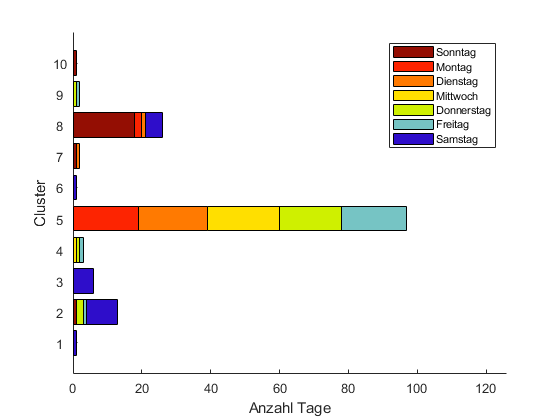


% Legends der Clusterlinien-Axes löschen (diese sind i.A. zu viele)
legend(axMainLines,'off')
legend(axSingleLines,'off')
% Achsenlabels ggfs. wieder aktivieren
set(axEigenschaften,'XTickMode','auto','XTickLabelMode','auto')

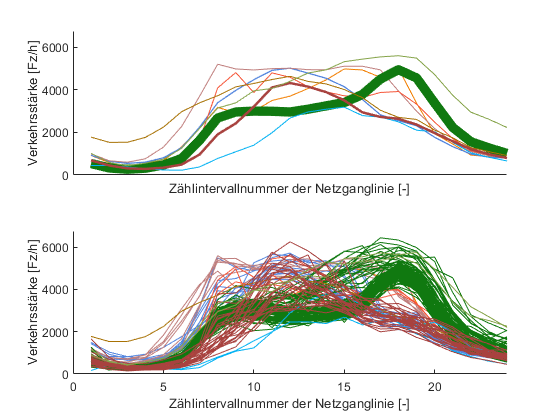

set(axMainLines,'XTick',[],'YTickMode','auto','YTickLabelMode','auto')
set(axSingleLines,'XTickMode','auto','XTickLabelMode','auto','YTickMode','auto','YTickLabelMode','auto')